# **Projeto Eletromag**

**1. Modelando a antena **

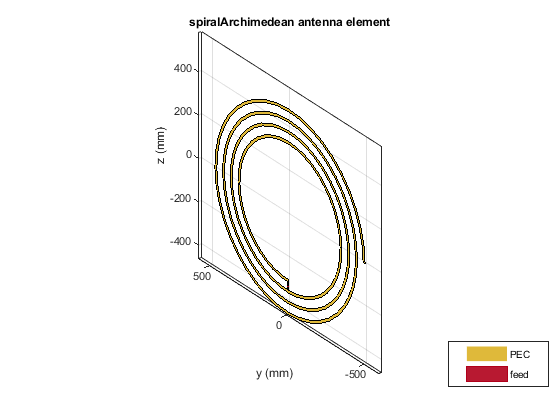

antE = spiralArchimedean('NumArms',1,'Turns',4, 'InnerRadius',30e-2, 'OuterRadius',50e-2,"Tilt",90,"TiltAxis","Y");
show(antE)

**2. Calculando a impedância de sua antena**

freq = linspace(4e7,6e7,200)

freq = 	1.0e+07 *

    4.0000    4.0101    4.0201    4.0302    4.0402    4.0503    4.0603    4.0704    4.0804    4.0905    4.1005    4.1106    4.1206    4.1307    4.1407    4.1508    4.1608    4.1709    4.1809    4.1910    4.2010    4.2111    4.2211    4.2312    4.2412    4.2513    4.2613    4.2714    4.2814    4.2915    4.3015    4.3116    4.3216    4.3317    4.3417    4.3518    4.3618    4.3719    4.3819    4.3920    4.4020    4.4121    4.4221    4.4322    4.4422    4.4523    4.4623    4.4724    4.4824    4.4925


impedancia = impedance(antE,freq)

impedancia = 	1.0e+04 *

   0.0001 + 0.0452i   0.0001 + 0.0460i   0.0001 + 0.0469i   0.0001 + 0.0478i   0.0001 + 0.0487i   0.0001 + 0.0496i   0.0001 + 0.0506i   0.0001 + 0.0516i   0.0001 + 0.0526i   0.0002 + 0.0537i   0.0002 + 0.0548i   0.0002 + 0.0559i   0.0002 + 0.0571i   0.0002 + 0.0583i   0.0002 + 0.0595i   0.0002 + 0.0608i   0.0002 + 0.0622i   0.0002 + 0.0636i   0.0002 + 0.0650i   0.0002 + 0.0666i   0.0003 + 0.0682i   0.0003 + 0.0698i   0.0003 + 0.0716i   0.0003 + 0.0734i   0.0003 + 0.0753i   0.0003 + 0.0773i   0.0004 + 0.0795i   0.0004 + 0.0817i   0.0004 + 0.0841i   0.0005 + 0.0866i   0.0005 + 0.0893i   0.0005 + 0.0921i   0.0006 + 0.0952i   0.0006 + 0.0984i   0.0007 + 0.1019i   0.0007 + 0.1057i   0.0008 + 0.1097i   0.0009 + 0.1141i   0.0009 + 0.1189i   0.0010 + 0.1242i   0.0012 + 0.1299i   0.0013 + 0.1362i   0.0015 + 0.1432i   0.0016 + 0.1511i   0.0019 + 0.1599i   0.0022 + 0.1699i   0.0025 + 0.1812i   0.0029 + 0.1944i   0.0035 + 0.2097i   0.0042 + 0.2278i


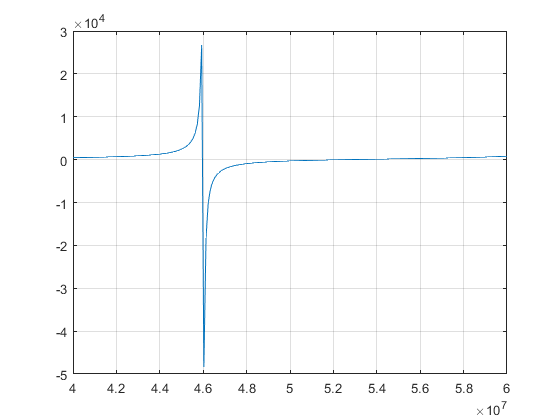

img = imag(impedancia);
plot(freq,img)
%ylim([-100, 100])
grid

% frequencia de ressonancia = 5.26e7 para img zero e wc = = 4.6e7

**3. Antena receptora**

antR = spiralArchimedean('NumArms',1,'Turns',4, 'InnerRadius',30e-2, 'OuterRadius',50e-2,'Tilt',90,"TiltAxis","Y");
show(antR)

Array de antenas

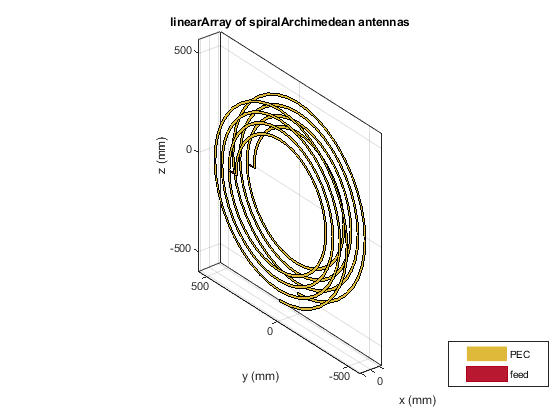

la = linearArray('Element',[antE,antR],'Tilt',90);
la.ElementSpacing = 10e-2;
show(la)

**4. Simulando o acoplamento**

ganhos = sparameters(la, freq);

**5. Visualizando os ganhos **

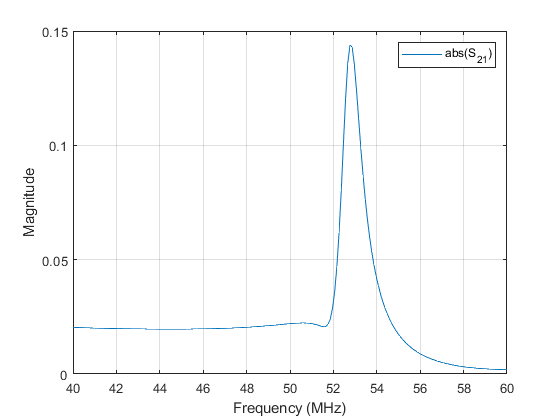

rfplot(ganhos,2,1,'abs')

ganhos_db = abs(rfparam(ganhos,2,1))

ganhos_db =     0.0204
    0.0204
    0.0203
    0.0203
    0.0203
    0.0202
    0.0202
    0.0202
    0.0201
    0.0201


**6. Visualização 3D** 

distancias = linspace(5e-2, 50e-2,8)
len_dist = length(distancias)
len_freq = length(freq)

distancias =     0.0500    0.1143    0.1786    0.2429    0.3071    0.3714    0.4357    0.5000


M_ganhos = []

len_dist = 8

len_freq = 200

for i = 1:length(distancias)


M_ganhos =

     []



lista_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176


lista_ganhos =     0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.0067    0.0067


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0054    0.0053    0.0052    0.0051    0.0050    0.0049    0.0049    0.0048    0.0047    0.0047    0.0046    0.0046    0.0045    0.0045    0.0044    0.0044    0.0044    0.0043    0.0043    0.0043    0.0043    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0043    0.0043    0.0043    0.0043    0.0044    0.0044    0.0044    0.0044    0.0045    0.0045


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0047    0.0047    0.0046    0.0045    0.0044    0.0044    0.0043    0.0042    0.0042    0.0041    0.0041    0.0040    0.0040    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038    0.0038    0.0038    0.0038    0.0039    0.0039    0.0039    0.0039    0.0040


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

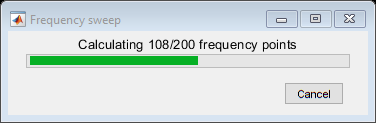

lista_ganhos =     0.0046    0.0046    0.0045    0.0044    0.0043    0.0043    0.0042    0.0041    0.0041    0.0040    0.0040    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0037    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038    0.0038    0.0038


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0047    0.0046    0.0045    0.0044    0.0043    0.0043    0.0042    0.0042    0.0041    0.0041    0.0040    0.0040    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038    0.0038


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0047    0.0046    0.0045    0.0044    0.0044    0.0043    0.0042    0.0042    0.0041    0.0041    0.0040    0.0040    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0037    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0047    0.0046    0.0045    0.0045    0.0044    0.0043    0.0043    0.0042    0.0041    0.0041    0.0040    0.0040    0.0040    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0037    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

    la.ElementSpacing = distancias(i);
    ganhos_3d = sparameters(la, freq);
    lista_ganhos = rot90(abs(rfparam(ganhos_3d,2,1)))
    M_ganhos = [M_ganhos;lista_ganhos]
end

M_ganhos

M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

Plotando o grafico 3d

mesh(freq, distancias, M_ganhos)

Unrecognized function or variable 'distancias'.

**Impedancia do modelo para diferentes frequencias**

sigma = 42;
wc = 4.6e7

wc = 46000000

L = sigma/wc

L = 9.1304e-07

C = 1/(sigma*wc)

C = 5.1760e-10

length(freq)

ans = 200


lista_impedancias = zeros(1,length(freq));

for i = 1:1:length(freq)
    w = freq(i);
    XL = 1i*w*L;
    XC = 1/(1i*w*C);
    impedancia_modelo = (XL*XC)/(XL+XC) + 4*XL;
    lista_impedancias(1,i) = impedancia_modelo;
end
length(lista_impedancias)

ans = 200

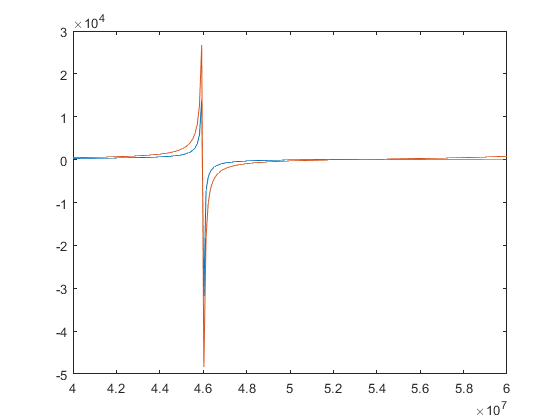

img_modelo = imag(lista_impedancias);
plot(freq,img_modelo,freq,img)

Ganho em Função mutua

Uf = 1

Uf = 1


lista_M = linspace(0, 1/wc, 100)

lista_M = 	1.0e+-7 *

         0    0.0022    0.0044    0.0066    0.0088    0.0110    0.0132    0.0154    0.0176    0.0198    0.0220    0.0242    0.0264    0.0285    0.0307    0.0329    0.0351    0.0373    0.0395    0.0417    0.0439    0.0461    0.0483    0.0505    0.0527    0.0549    0.0571    0.0593    0.0615    0.0637    0.0659    0.0681    0.0703    0.0725    0.0747    0.0769    0.0791    0.0812    0.0834    0.0856    0.0878    0.0900    0.0922    0.0944    0.0966    0.0988    0.1010    0.1032    0.1054    0.1076


lista_ganhos = zeros(1,length(lista_M));
for n = 1:1:length(lista_M)
    Xm  = 1i*wc*lista_M(n)
    Z = [1 -Xm;
         Xm -1];
    V = [Uf;0];
    I = rot90(linsolve(Z,V))
    lista_ganhos(1,n) = abs((I(2)/I(1))^2)
end

Xm = 0

I =      1     0


lista_ganhos =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Xm = 0.0000 + 0.0101i

I =    0.9999 + 0.0000i   0.0000 + 0.0101i


lista_ganhos = 	1.0e+-3 *

         0    0.1020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.0202i

I =    0.9996 + 0.0000i   0.0000 + 0.0202i


lista_ganhos = 	1.0e+-3 *

         0    0.1020    0.4081         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.0303i

I =    0.9991 + 0.0000i   0.0000 + 0.0303i


lista_ganhos = 	1.0e+-3 *

         0    0.1020    0.4081    0.9183         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.0404i

I =    0.9984 + 0.0000i   0.0000 + 0.0403i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.0505i

I =    0.9975 + 0.0000i   0.0000 + 0.0504i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.0606i

I =    0.9963 + 0.0000i   0.0000 + 0.0604i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.0707i

I =    0.9950 + 0.0000i   0.0000 + 0.0704i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.0808i

I =    0.9935 + 0.0000i   0.0000 + 0.0803i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.0909i

I =    0.9918 + 0.0000i   0.0000 + 0.0902i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1010i

I =    0.9899 + 0.0000i   0.0000 + 0.1000i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1111i

I =    0.9878 + 0.0000i   0.0000 + 0.1098i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1212i

I =    0.9855 + 0.0000i   0.0000 + 0.1195i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1313i

I =    0.9830 + 0.0000i   0.0000 + 0.1291i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1414i

I =    0.9804 + 0.0000i   0.0000 + 0.1386i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1515i

I =    0.9776 + 0.0000i   0.0000 + 0.1481i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1616i

I =    0.9745 + 0.0000i   0.0000 + 0.1575i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1717i

I =    0.9714 + 0.0000i   0.0000 + 0.1668i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1818i

I =    0.9680 + 0.0000i   0.0000 + 0.1760i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.1919i

I =    0.9645 + 0.0000i   0.0000 + 0.1851i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.2020i

I =    0.9608 + 0.0000i   0.0000 + 0.1941i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.2121i

I =    0.9569 + 0.0000i   0.0000 + 0.2030i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.2222i

I =    0.9529 + 0.0000i   0.0000 + 0.2118i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.2323i

I =    0.9488 + 0.0000i   0.0000 + 0.2204i


lista_ganhos =          0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Xm = 0.0000 + 0.2424i

I =    0.9445 + 0.0000i   0.0000 + 0.2290i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588         0         0         0         0         0


Xm = 0.0000 + 0.2525i

I = 1×2
   0.9401 + 0.0000i   0.0000 + 0.2374i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638         0         0         0         0


Xm = 0.0000 + 0.2626i

I = 1×2
   0.9355 + 0.0000i   0.0000 + 0.2457i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690         0         0         0


Xm = 0.0000 + 0.2727i

I = 1×2
   0.9308 + 0.0000i   0.0000 + 0.2538i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744         0         0


Xm = 0.0000 + 0.2828i

I = 1×2
   0.9259 + 0.0000i   0.0000 + 0.2619i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800         0


Xm = 0.0000 + 0.2929i

I = 1×2
   0.9210 + 0.0000i   0.0000 + 0.2698i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3030i

I = 1×2
   0.9159 + 0.0000i   0.0000 + 0.2775i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3131i

I = 1×2
   0.9107 + 0.0000i   0.0000 + 0.2852i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3232i

I = 1×2
   0.9054 + 0.0000i   0.0000 + 0.2927i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3333i

I = 1×2
   0.9000 + 0.0000i   0.0000 + 0.3000i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3434i

I = 1×2
   0.8945 + 0.0000i   0.0000 + 0.3072i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3535i

I = 1×2
   0.8889 + 0.0000i   0.0000 + 0.3143i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3636i

I = 1×2
   0.8832 + 0.0000i   0.0000 + 0.3212i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3737i

I = 1×2
   0.8774 + 0.0000i   0.0000 + 0.3279i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3838i

I = 1×2
   0.8716 + 0.0000i   0.0000 + 0.3345i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.3939i

I = 1×2
   0.8657 + 0.0000i   0.0000 + 0.3410i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4040i

I = 1×2
   0.8597 + 0.0000i   0.0000 + 0.3473i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4141i

I = 1×2
   0.8536 + 0.0000i   0.0000 + 0.3535i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4242i

I = 1×2
   0.8475 + 0.0000i   0.0000 + 0.3595i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4343i

I = 1×2
   0.8413 + 0.0000i   0.0000 + 0.3654i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4444i

I = 1×2
   0.8351 + 0.0000i   0.0000 + 0.3711i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4545i

I = 1×2
   0.8288 + 0.0000i   0.0000 + 0.3767i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4646i

I = 1×2
   0.8224 + 0.0000i   0.0000 + 0.3821i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4747i

I = 1×2
   0.8161 + 0.0000i   0.0000 + 0.3874i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4848i

I = 1×2
   0.8097 + 0.0000i   0.0000 + 0.3926i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.4949i

I = 1×2
   0.8032 + 0.0000i   0.0000 + 0.3976i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5051i

I = 1×2
   0.7968 + 0.0000i   0.0000 + 0.4024i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5152i

I = 1×2
   0.7903 + 0.0000i   0.0000 + 0.4071i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5253i

I = 1×2
   0.7838 + 0.0000i   0.0000 + 0.4117i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5354i

I = 1×2
   0.7772 + 0.0000i   0.0000 + 0.4161i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5455i

I = 1×2
   0.7707 + 0.0000i   0.0000 + 0.4204i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5556i

I = 1×2
   0.7642 + 0.0000i   0.0000 + 0.4245i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5657i

I = 1×2
   0.7576 + 0.0000i   0.0000 + 0.4285i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5758i

I = 1×2
   0.7510 + 0.0000i   0.0000 + 0.4324i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5859i

I = 1×2
   0.7445 + 0.0000i   0.0000 + 0.4362i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.5960i

I = 1×2
   0.7379 + 0.0000i   0.0000 + 0.4398i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6061i

I = 1×2
   0.7314 + 0.0000i   0.0000 + 0.4433i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6162i

I = 1×2
   0.7248 + 0.0000i   0.0000 + 0.4466i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6263i

I = 1×2
   0.7183 + 0.0000i   0.0000 + 0.4498i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6364i

I = 1×2
   0.7118 + 0.0000i   0.0000 + 0.4529i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6465i

I = 1×2
   0.7053 + 0.0000i   0.0000 + 0.4559i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6566i

I = 1×2
   0.6988 + 0.0000i   0.0000 + 0.4588i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6667i

I = 1×2
   0.6923 + 0.0000i   0.0000 + 0.4615i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6768i

I = 1×2
   0.6859 + 0.0000i   0.0000 + 0.4642i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6869i

I = 1×2
   0.6794 + 0.0000i   0.0000 + 0.4667i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.6970i

I = 1×2
   0.6731 + 0.0000i   0.0000 + 0.4691i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7071i

I = 1×2
   0.6667 + 0.0000i   0.0000 + 0.4714i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7172i

I = 1×2
   0.6604 + 0.0000i   0.0000 + 0.4736i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7273i

I = 1×2
   0.6541 + 0.0000i   0.0000 + 0.4757i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7374i

I = 1×2
   0.6478 + 0.0000i   0.0000 + 0.4777i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7475i

I = 1×2
   0.6416 + 0.0000i   0.0000 + 0.4795i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7576i

I = 1×2
   0.6354 + 0.0000i   0.0000 + 0.4813i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7677i

I = 1×2
   0.6292 + 0.0000i   0.0000 + 0.4830i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7778i

I = 1×2
   0.6231 + 0.0000i   0.0000 + 0.4846i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7879i

I = 1×2
   0.6170 + 0.0000i   0.0000 + 0.4861i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.7980i

I = 1×2
   0.6110 + 0.0000i   0.0000 + 0.4875i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8081i

I = 1×2
   0.6050 + 0.0000i   0.0000 + 0.4889i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8182i

I = 1×2
   0.5990 + 0.0000i   0.0000 + 0.4901i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8283i

I = 1×2
   0.5931 + 0.0000i   0.0000 + 0.4913i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8384i

I = 1×2
   0.5872 + 0.0000i   0.0000 + 0.4923i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8485i

I = 1×2
   0.5814 + 0.0000i   0.0000 + 0.4933i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8586i

I = 1×2
   0.5756 + 0.0000i   0.0000 + 0.4942i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8687i

I = 1×2
   0.5699 + 0.0000i   0.0000 + 0.4951i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8788i

I = 1×2
   0.5642 + 0.0000i   0.0000 + 0.4959i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8889i

I = 1×2
   0.5586 + 0.0000i   0.0000 + 0.4966i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.8990i

I = 1×2
   0.5530 + 0.0000i   0.0000 + 0.4972i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9091i

I = 1×2
   0.5475 + 0.0000i   0.0000 + 0.4977i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9192i

I = 1×2
   0.5420 + 0.0000i   0.0000 + 0.4982i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9293i

I = 1×2
   0.5366 + 0.0000i   0.0000 + 0.4987i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9394i

I = 1×2
   0.5312 + 0.0000i   0.0000 + 0.4990i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9495i

I = 1×2
   0.5259 + 0.0000i   0.0000 + 0.4993i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9596i

I = 1×2
   0.5206 + 0.0000i   0.0000 + 0.4996i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9697i

I = 1×2
   0.5154 + 0.0000i   0.0000 + 0.4998i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9798i

I = 1×2
   0.5102 + 0.0000i   0.0000 + 0.4999i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 0.9899i

I = 1×2
   0.5051 + 0.0000i   0.0000 + 0.5000i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


Xm = 0.0000 + 1.0000i

I = 1×2
   0.5000 + 0.0000i   0.0000 + 0.5000i


lista_ganhos = 1×100
         0    0.0001    0.0004    0.0009    0.0016    0.0026    0.0037    0.0050    0.0065    0.0083    0.0102    0.0123    0.0147    0.0172    0.0200    0.0230    0.0261    0.0295    0.0331    0.0368    0.0408    0.0450    0.0494    0.0540    0.0588    0.0638    0.0690    0.0744    0.0800    0.0858


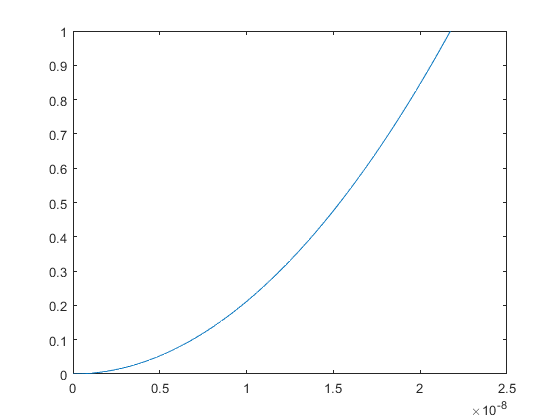


plot(lista_M,lista_ganhos)